# Effect of dimensionality on cooling rate

clear all, close all, clc
set_defaults()

## Simulation in self-similar coordinates

A scaling analysis has shown that the long-term evolution of a localized heat anomaly is self-similar in the following similarity variables:

$\eta = \frac{x}{\sqrt{4D\,t}}$ and $\theta(\eta) = \frac{\rho c_p}{E}(4 D t)^{d/2} T(x,t)$

If simulation results are plotted in the similarity variables, the solution should stop changing after the details of the initial conditions have dissipated.

radius = .1;
dim = 3;
close all
[T0,Grid] = initial_condition(dim,radius);

dim = 3: r = 0.10 and T0 = 238.73. => E = 1.00


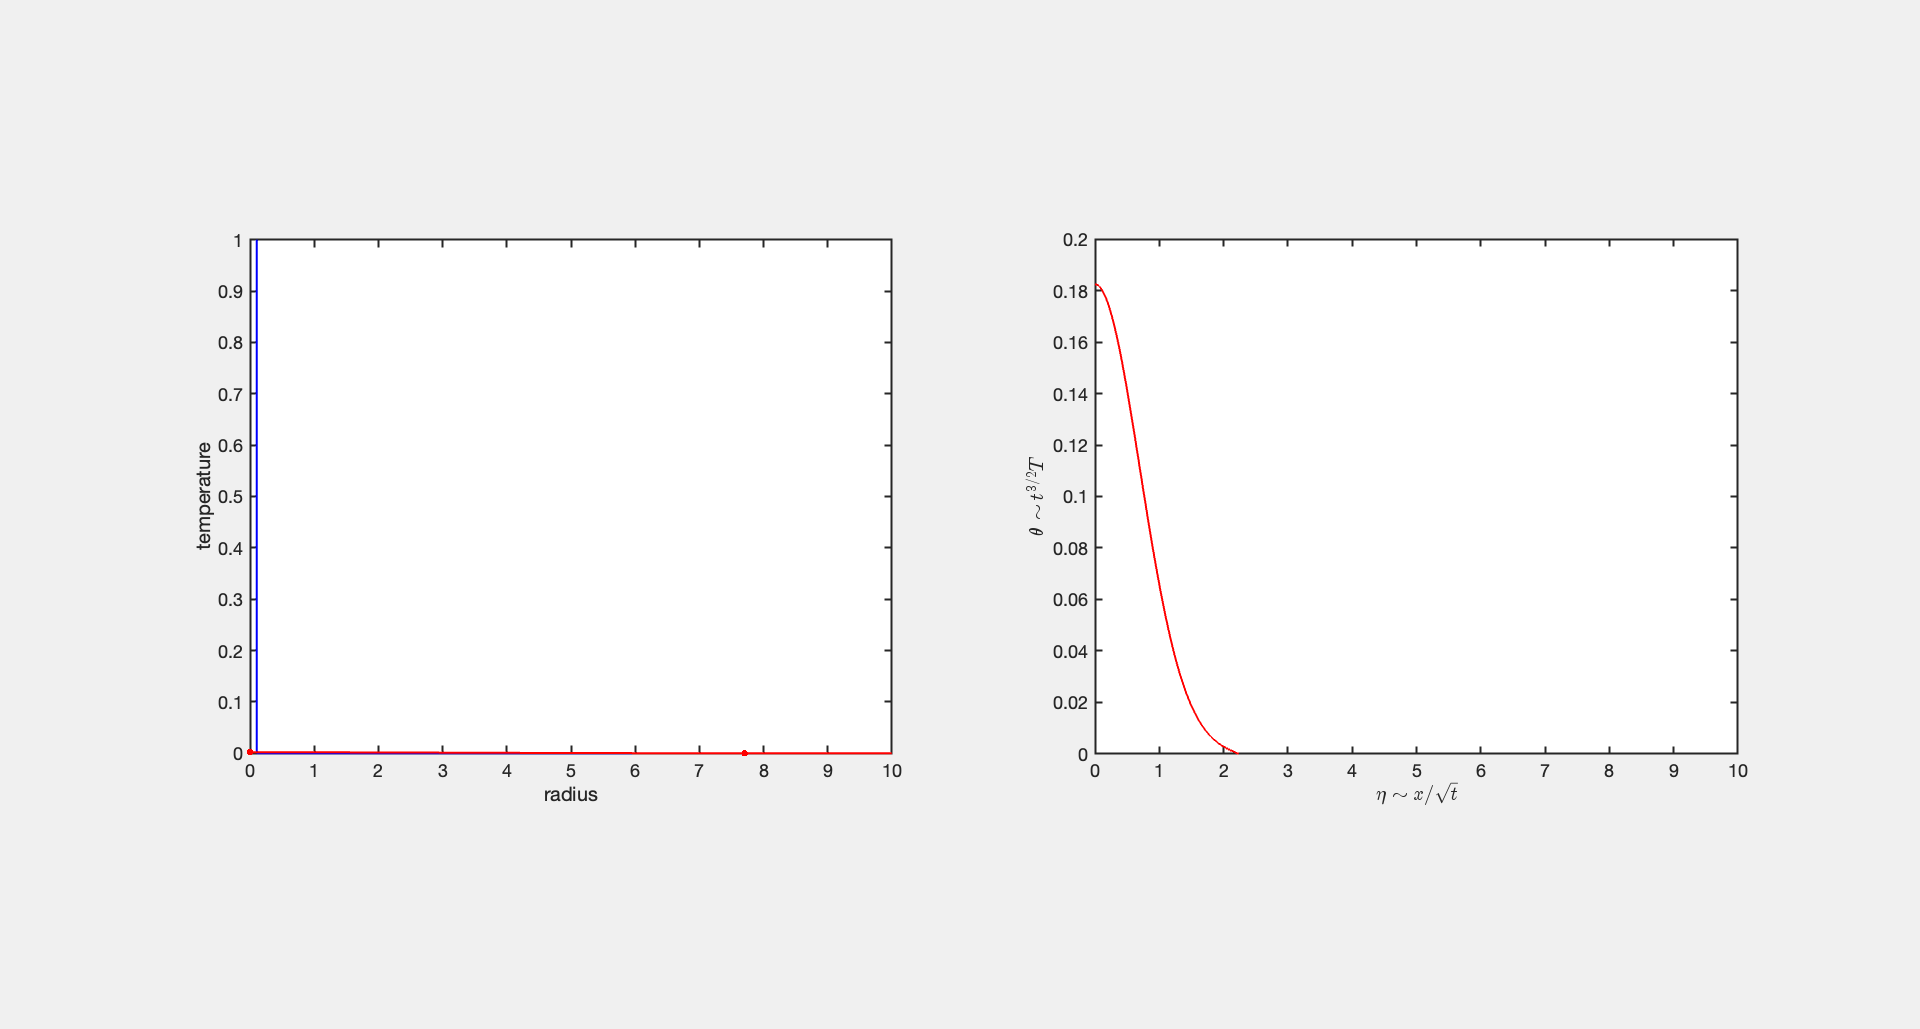

[u,umax,xf,tvec,eta,theta] = evolve_temp(T0,Grid,5,dim);

After some time the solution in the similarity variables stops changing, confirming that self-similar nature of the solution.

## Scaling laws for T-decay and T-propagation

The similarity variable suggests the following scaling laws:

- Temperature decay:            $T \sim t^{-d/2}$

- Temperature propagation:   $x_f \sim \sqrt{t} \theta^{-1}(t^{d/2})$

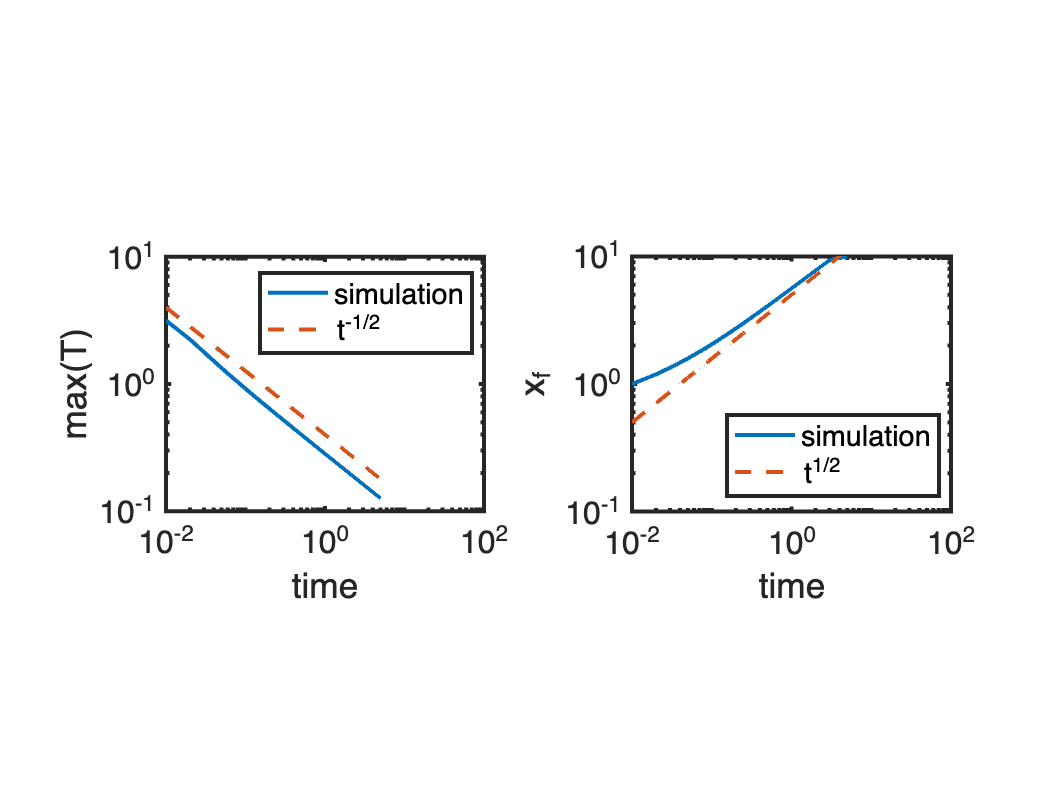

load dim_1.mat
umax1 = umax; xf1 = xf; tvec1 = tvec; eta1 = eta; theta1 = theta;
figure
subplot 121
loglog(tvec1(2:end),umax1(2:end),'-'), hold on
loglog(tvec1(2:end),.4./tvec1(2:end).^(dim/2),'--')
xlabel('time'), ylabel('max(T)')
xlim([1e-2 1e2]), ylim([1e-1 1e1])
legend('simulation','t^{-1/2}')
pbaspect([1 .8 1])

subplot 122
loglog(tvec1(2:end),xf1(2:end)-radius,'-'), hold on
loglog(tvec1(2:end),5*sqrt(tvec1(2:end)),'--'), hold off
xlabel('time'), ylabel('x_f')
xlim([1e-2 1e2]), ylim([1e-1 1e1])
legend('simulation','t^{1/2}','location','southeast')
pbaspect([1 .8 1])

## Temperature decay in different geometries

The scaling laws suggest that temperature anaomalies in cylindrical and spherical geometries decay more rapidly than in linear problems.

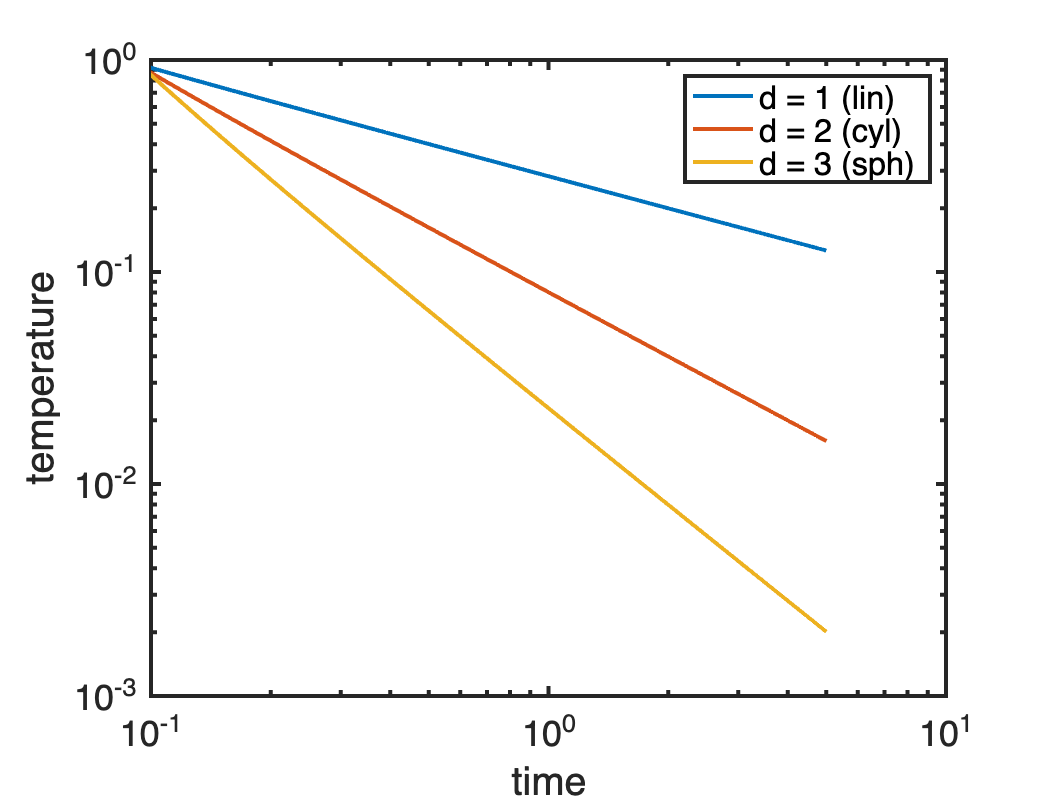

load dim_2.mat
umax2 = umax; xf2 = xf; tvec2 = tvec; eta2 = eta; theta2 = theta;
load dim_3.mat
umax3 = umax; xf3 = xf; tvec3 = tvec; eta3 = eta; theta3 = theta;
figure
loglog(tvec1(2:end),umax1(2:end),'-'), hold on
loglog(tvec2(2:end),umax2(2:end),'-')
loglog(tvec3(2:end),umax3(2:end),'-'), hold off
legend('d = 1 (lin)','d = 2 (cyl)','d = 3 (sph)')
pbaspect([1 .8 1])
xlabel('time'), ylabel('temperature')
xlim([1e-1 1e1]), ylim([1e-3 1e0])

## Shape of the long-term T-distribution

In all three geometries the long-term T-distribution is Gaussian.

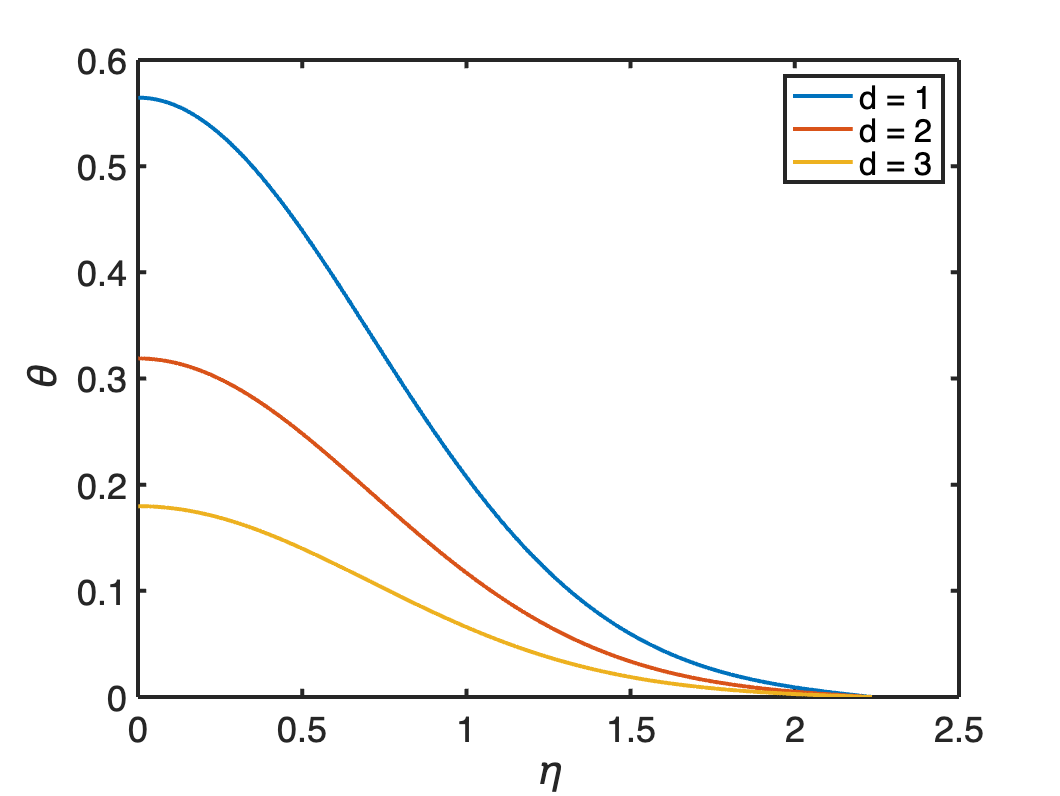

figure
plot(eta1,theta1,'-',eta2,theta2,'-',eta3,theta3,'-')
xlabel '\eta', ylabel '\theta'
legend('d = 1','d = 2','d = 3')

# Auxillary functions

## evolve_temp()

function [u,umax,xf,tvec,eta,theta] = evolve_temp(T0,Grid,tmax,dim)
dt = 5e-2;
Nt = tmax/dt;
umax = zeros(Nt+1,1); xf = umax; tvec = umax;
theta = 0; % Backward Euler
tol = 1e-4;
% Discrete operators
[D,G,~,I,M] = build_ops(Grid);
L = -D*G; M = I;
IM = @(theta,dt) M + (1-theta)*dt*L;
EX = @(theta,dt) M - theta*dt*L;
fs = spalloc(Grid.Nx,1,0);
Im = IM(theta,dt); Ex = EX(theta,dt);

% Boundary condtions
Param.dof_dir   = [Grid.dof_xmax];
Param.dof_f_dir = [Grid.dof_f_xmax];
Param.g = [0];
Param.dof_neu = [];
Param.dof_f_neu = [];
[B,N,fn] = build_bnd(Param,Grid,I);

% Solve evolution
time = 0;
u = T0;
umax(1) = max(u); tvec(1) = time;
xf(1)   = find_xf(Grid,u,tol);
subplot 121
plot(Grid.xc,u,'-'), hold on
plot(xf(1),tol,'o'), hold off

umin = -ones(Nt,1); tvec = umin;
set(gcf,'Visible','on') % This line is only necessary in live-scripts
plot(Grid.xc,T0,'-')
xlabel 'radius', ylabel 'temperature'
pbaspect([1 .8 1])
ylim([0 1]), xlim([0 10])
for i = 1:Nt
    time = time + dt;
    u = solve_lbvp(Im,Ex*u+dt*fs+fn,B,Param.g,N);
    xf(i+1)   = find_xf(Grid,u,tol);
    umax(i+1) = max(u); tvec(i+1) = time;
    
    % Self-similar variables
    eta = Grid.xc./sqrt(4*time);
    theta = u*(4*time)^(dim/2);
    
    subplot 121
    plot(Grid.xc,T0,'b-',Grid.xc,u,'r-'), hold on
    plot(0,umax(i+1),'r.','markersize',16)
    plot(xf(i+1),tol,'r.','markersize',16), hold off
    pbaspect([1 .8 1])
    ylim([0 1]), 
    xlim([0 10])
    xlabel 'radius'
    ylabel 'temperature'
    
    subplot 122
    plot(eta,theta,'r')
    xlim([0 10])
    pbaspect([1 .8 1])
    xlabel('$\eta \sim x/\sqrt{t}$','interpreter','latex')
    if dim == 1
        ylabel('$\theta \sim t^{1/2} T$','interpreter','latex')
        ylim([0 .6])
    elseif dim == 2
        ylabel('$\theta \sim t T$','interpreter','latex')
        ylim([0 .4])
    elseif dim == 3
        ylabel('$\theta \sim t^{3/2} T$','interpreter','latex')
        ylim([0 .2])
    end
    drawnow
    pause(.1)
end

end

## find_xf()

function [xf] = find_xf(Grid,u,epsilon)
uint = @(xint) interp1(Grid.xc,u,xint,'linear');
obj = @(x) (uint(x)-epsilon).^2;
xf0 = Grid.xc(u > epsilon); xf0 = max(xf0);
xf = fminsearch(obj,xf0);
end

## initial_condition()

function [T0,Grid] = initial_condition(dim,radius)
Grid.xmin = 0; Grid.xmax = radius*1e2; Grid.Nx = 1e3;
% Initial condition
if dim == 1
    Grid.geom = 'cartesian';
    u0 = 1/(2*radius);
elseif dim == 2
    Grid.geom = 'cylindrical_r';
    u0 = 1/(pi*radius^2);
    E = pi*radius^2*u0;
elseif dim == 3
    Grid.geom = 'spherical_r';
    u0 = 3/(4*pi*radius.^3);
    E = 4/3*pi*radius.^3*u0;
end
Grid = build_grid(Grid);

T0 = zeros(Grid.Nx,1); T0(Grid.xc<=radius) = u0;
E0 = sum(Grid.V.*T0);
fprintf('dim = %d: r = %3.2f and T0 = %3.2f. => E = %3.2f\n',dim,radius,u0,E0)
end

## set_defaults()

function [] = set_defaults()
set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end
